a = 0 

a = 0

b = 14

b = 14

x = linspace(a,b,500)

x =          0    0.0281    0.0561    0.0842    0.1122    0.1403    0.1683    0.1964    0.2244    0.2525    0.2806    0.3086    0.3367    0.3647    0.3928    0.4208    0.4489    0.4770    0.5050    0.5331    0.5611    0.5892    0.6172    0.6453    0.6733    0.7014    0.7295    0.7575    0.7856    0.8136    0.8417    0.8697    0.8978    0.9259    0.9539    0.9820    1.0100    1.0381    1.0661    1.0942    1.1222    1.1503    1.1784    1.2064    1.2345    1.2625    1.2906    1.3186    1.3467    1.3747


h = 0.001 

h = 1.0000e-03

iter=1000 

iter = 1000

eps=0.001

eps = 1.0000e-03

f=@(x)sin(x)./x

f = function_handle with value:
    @(x)sin(x)./x


y=f(x)

y =        NaN    0.9999    0.9995    0.9988    0.9979    0.9967    0.9953    0.9936    0.9916    0.9894    0.9869    0.9842    0.9812    0.9780    0.9745    0.9707    0.9668    0.9625    0.9580    0.9533    0.9483    0.9431    0.9377    0.9320    0.9261    0.9200    0.9136    0.9071    0.9003    0.8933    0.8860    0.8786    0.8710    0.8631    0.8551    0.8469    0.8384    0.8298    0.8210    0.8121    0.8029    0.7936    0.7841    0.7745    0.7647    0.7547    0.7446    0.7344    0.7240    0.7135


plot(x,f(x),x,0*x,':') 
grid on
xlabel('x')
ylabel('y')
hold on
ymin=min(y)

ymin = -0.2172

ymax=max(y)

ymax = 0.9999

if ymin<0 
    ymin=1.1*ymin
else 
    ymin=0.9*ymin
end

ymin = -0.2390

if ymax>0 
    ymax=1.1*ymax
else 
    ymax=0.9*ymax
end

ymax = 1.0999

axis([a,b,ymin,ymax])
z = ginput(2)

z =     2.0239    0.4445
    3.6740   -0.1342


z1=z(1,1)

z1 = 2.0239

z2=z(2,1)

z2 = 3.6740

f1 = f(z1)

f1 = 0.4442

f2=f(z2)

f2 = -0.1382

z=(z1+z2)/2 

z = 2.8490

y=f(z)

y = 0.1012

P = plot(z1,0,'*',z2,0,'*',z,0,'o')

P =   3×1 Line array:

  Line
  Line
  Line


if f1*f2>0 
    'Плохие точки'
end
for i=1:iter
z=(z1+z2)/2; y=f(z)
delete(P);
P=plot(z1,0,'*',z2,0,'*',z,0,'o')
if y*f1<0
z2=z
else 
    z1=z
end
if abs(f(z))<eps
break
end
end

y = 0.1012

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 2.8490

y = -0.0367

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 3.2615

y = 0.0282

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.0552

y = -0.0053

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 3.1584

y = 0.0112

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.1068

y = 0.0029

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.1326

y = -0.0012

P =   3×1 Line array:

  Line
  Line
  Line


z2 = 3.1455

y = 8.1244e-04

P =   3×1 Line array:

  Line
  Line
  Line


z1 = 3.1390

disp("Найденный корень " + z)

Найденный корень 3.139


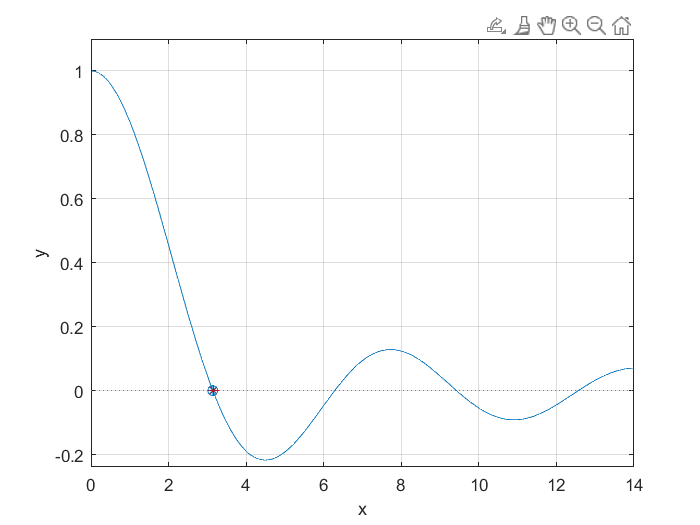

hold off